# Sistemas de Visión Artificial

# **Práctica 1. Ejemplo de detector de movimiento**

**Autor(es): Franck Michael Fierro Chicaiza**

**Fecha: 21/09/2023**

Analice el código del siguiente detector de movimiento e incluya alguna de las modificaciones realizada sobre la captura en el imageAcquisitionExplorer (cambio de tamaño de la imagen, brillo, contraste, etc.).

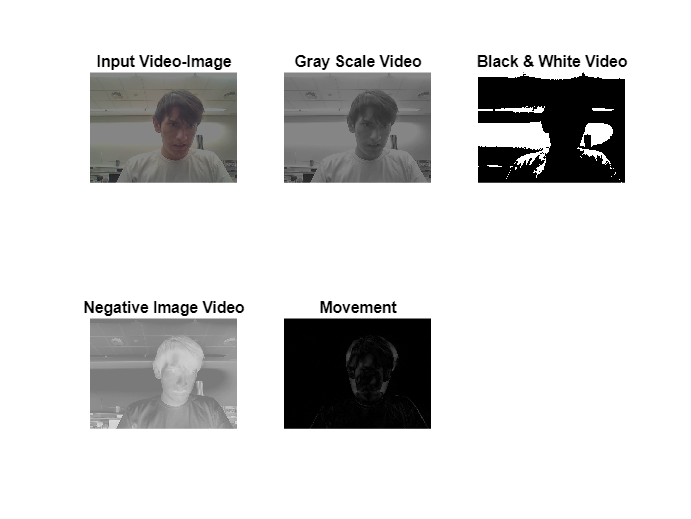


clear all
close all

clc

% Cambio en la resolucion de video
vid = videoinput('winvideo', 1, "YUY2_640x480");

% Cambios en los atributos del video
vid.ReturnedColorspace = "rgb";
src = getselectedsource(vid);
src.Brightness = 19;
src.Contrast = 15;
src.Exposure = -3;
src.Gain = 6;
src.Hue = -10;
src.Saturation = 39;

set(vid,'TriggerRepeat',Inf);
vid.FrameGrabInterval = 5;
start(vid);
try
    while(vid.FramesAcquired<=110) % Stop after 110 frames
        IM = getdata(vid,2);
        IMGray = rgb2gray(IM(:,:,1:3));
        IMbw=im2bw(IMGray,0.5);
        IMneg=imadjust(IMGray,[0 1],[1 0]);

        subplot(2,3,1);imshow(IM(:,:,:,1));title('Input Video-Image')
        subplot(2,3,2);imshow(IMGray);title('Gray Scale Video')
        subplot(2,3,3);imshow(IMbw);title('Black & White Video')
        subplot(2,3,4);imshow(IMneg);title('Negative Image Video')
        
        %*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*
        i1=IM(:,:,:,1);
        i2=IM(:,:,:,2);
        i1=rgb2gray(i1(:,:,1:3));
        i2=rgb2gray(i2(:,:,1:3));
        m=abs(double(i1)-double(i2))/256;
        subplot(2,3,5);imshow(m);title('Movement')
    end
    stop(vid);
catch
    stop(vid);
end